# Topology Visualization

This demo is to show the backhaul network topologies used in the C++ simulation.

clear;
clc;
close all;

Random seed = 200, numRelays = 1152, all bss;

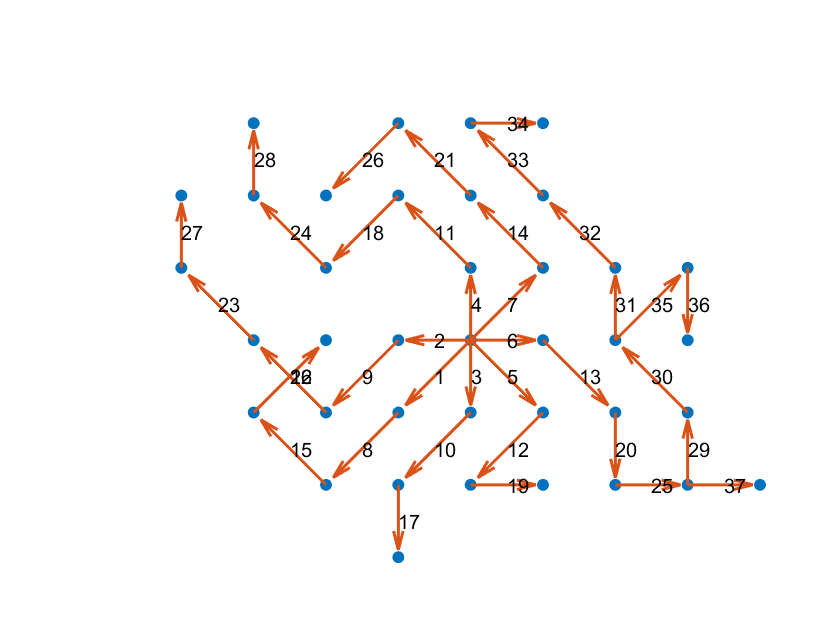

fileID = fopen('../../Data/Base_Stations_Grid/Data_BSInGrid_508_1152_200_5.txt');
C = textscan(fileID,'%f\t%f');
fclose(fileID);
bsGridIndex = cell2mat(C);
figure;
scatter(bsGridIndex(:,1), bsGridIndex(:,2),'filled');
hold on;
fileID = fopen('../../Data/Topology/Data_Topology_Tree_508_1152_38.txt');
C = textscan(fileID,'%f\t%f');
fclose(fileID);
bsLinks = cell2mat(C);
numRelays = 1152;
bsLinks = bsLinks - numRelays + 1;
pX = bsGridIndex(bsLinks(:,1),1);
pY = bsGridIndex(bsLinks(:,1),2);
vX = bsGridIndex(bsLinks(:,2),1) - bsGridIndex(bsLinks(:,1),1);
vY = bsGridIndex(bsLinks(:,2),2) - bsGridIndex(bsLinks(:,1),2);
quiver(pX,pY,vX,vY,'LineWidth',1.5,'MaxHeadSize',0.1);
for i = 1:length(bsLinks(:,1))
    txt = num2str(i);
    tX = (bsGridIndex(bsLinks(i,2),1) + bsGridIndex(bsLinks(i,1),1))/2;
    tY = (bsGridIndex(bsLinks(i,2),2) + bsGridIndex(bsLinks(i,1),2))/2;
    text(tX, tY, txt, 'FontSize', 10);
end
axis off;
daspect([1 1 1]);

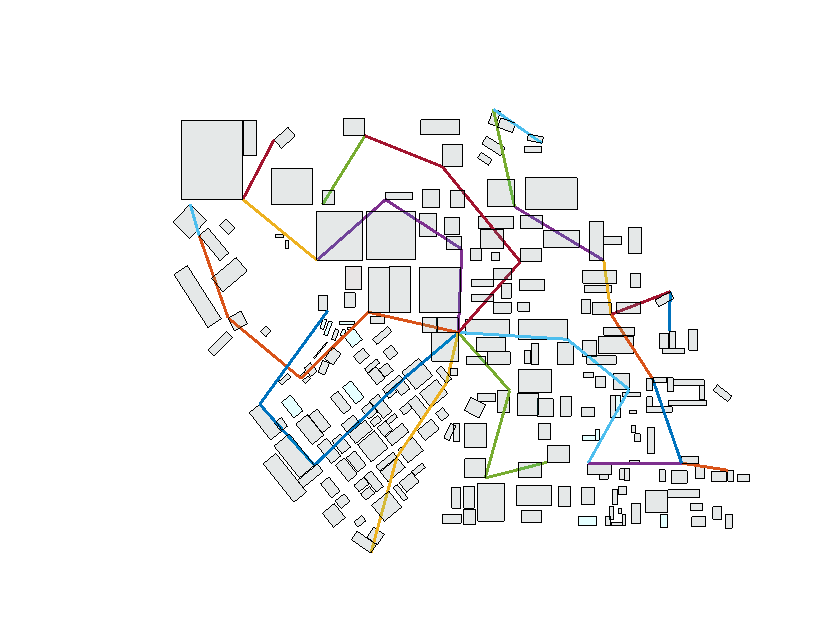

figure;
fileID = fopen('../../Data/Building_Vertices/Data_BuildingVertices.txt');
C = textscan(fileID,'%f,%f,%f');
fclose(fileID);
A = cell2mat(C);
numBuildings = length(A(:,1))/8;
% A B C D Ah Bh Ch Dh
% 1 2 3 4 5  6  7  8
for i=1:numBuildings
    patch('Vertices',A(8*(i-1)+1:8*i,:),'Faces',[1,2,3,4;1,2,6,5;2,3,7,6;3,4,8,7;4,1,5,8;5,6,7,8],...
        'FaceVertexCData',hsv(8),'FaceAlpha',0.1,'FaceColor','flat');
end
hold on
fileID = fopen('../../Data/Relays/Data_Relays_Surface_508_0.000100_1.txt');
C = textscan(fileID,'%f,%f,%f');
fclose(fileID);
A = cell2mat(C);
fileID = fopen('../../Data/Base_Stations/Data_BSSet_508_1152_200.000000_5.txt');
C = textscan(fileID,'%f,%f,%f');
fclose(fileID);
B = cell2mat(C);
A = [A;B];
for i = 1:length(bsLinks(:,1))
    src = A(bsLinks(i,1)+1152,:);
    dst = A(bsLinks(i,2)+1152,:);
    X = [src(1);dst(1)];
    Y = [src(2);dst(2)];
    Z = [src(3);dst(3)];
    plot3(X,Y,Z,'LineWidth',1.5);hold on;
end
view(2);
axis off;


% fileID = fopen('Results/pathpoints170221135247.txt');
% P = textscan(fileID,'%f,%f,%f');
% fclose(fileID);
% B = cell2mat(P);
% src = B(1,:);
% dst = B(end,:);
% for i = 1:length(B(:,1))
%     if(isequal(B(i,:),src))
%         idx1 = i;
%         j = idx1+1;
%         while(~isequal(B(j,:),dst))
%             j=j+1;
%         end
%         idx2 = j;
%         plot3(B(idx1:idx2,1),B(idx1:idx2,2),B(idx1:idx2,3),'LineWidth',1.5);hold on;
%         i = j+1;
%    end
% end